startup_rvc

Robotics, Vision & Control: (c) Peter Corke 1992-2020 http://www.petercorke.com
- Robotics Toolbox for MATLAB (release 10.4)
 - ARTE contributed code: 3D models for robot manipulators (C:\Program Files\MATLAB\R2024a\toolbox\rvctools\robot\data\meshes)
 - pHRIWARE (release 1.2): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2024) (c)
- Machine Vision Toolbox for MATLAB (release 4.3)
 - VGG contributed code (C:\Program Files\MATLAB\R2024a\toolbox\rvctools\contrib\vgg)
 - graphseg contributed code (C:\Program Files\MATLAB\R2024a\toolbox\rvctools\contrib\graphseg)
- Spatial Math Toolbox for MATLAB (release 1.0)


syms q1
syms q2
syms q3
sympref('AbbreviateOutput',false);

L(1) = Link([0,0,1,0]);
L(2) = Link([0,0,1,0]);
L(3) = Link([0,0,1,0]);



robot = SerialLink(L, 'name', 'Articulated');



kine = fkine(robot, [q1, q2, q3])

$$\left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right) & 0 & \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & 0 & \sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$



jacobian = jacob0(robot, [q1, q2, q3]);


disp(jacobian)

$$\left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}+q_{3}\right)\,\left(\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{3}\right)\right)-\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left(\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{3}\right)+1\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)\,\sin\left(q_{3}\right)-\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left(\cos\left(q_{3}\right)+1\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)\,\left(\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{3}\right)+1\right)+\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left(\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{3}\right)\right) & \sin\left(q_{1}+q_{2}+q_{3}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}+q_{2}+q_{3}\right)\,\left(\cos\left(q_{3}\right)+1\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

jacobian = simplify(jacobian) 

$$jacobian = \left(\begin{array}{ccc} -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

jacobian = [jacobian(1,:);jacobian(2,:);jacobian(6,:)]

$$jacobian = \left(\begin{array}{ccc} -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)\\ 1 & 1 & 1 \end{array}\right)$$

val = solve((det(jacobian) == 0),[q1])

 
val =
 
Empty sym: 0-by-1
 


val = solve((det(jacobian) == 0),[q2])

$$val = \left(\begin{array}{c} 0\\ -q_{1}-\log\left(-{\mathrm{e}}^{q_{1}\,\mathrm{i}}\right)\,\mathrm{i} \end{array}\right)$$

val = solve((det(jacobian) == 0),[q3])

 
val =
 
Empty sym: 0-by-1
 


val = solve((det(jacobian) == 0),[q1, q2])

val = struct with fields:
    q1: 0
    q2: 0


val = solve((det(jacobian) == 0),[q2, q3])

val = struct with fields:
    q2: [2×1 sym]
    q3: [2×1 sym]


val = solve((det(jacobian) == 0),[q1, q2, q3])

val = struct with fields:
    q1: 0
    q2: 0
    q3: 0


% val.q2
% val.q3

d = det(jacobian)

$$d = \sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{1}\right)-\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)$$

subs(d, [q1,q2], [0,0])

$$ans = 0$$

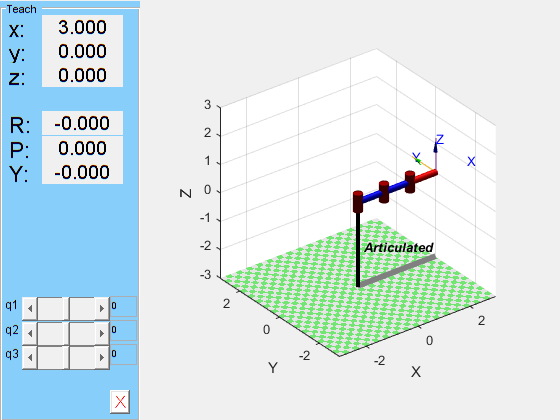


teach(robot)